# Matlab usage for formant manipulation

## Introduction

This text documents the usage of several Matlab functions that are used for the generation of stimuli for the study of interactions between voice and speech properties.

% Do adapt paths to your own installation
addpath('~/work/lib/UMCG/matlab/fmanipulation');

straight_path = '~/work/lib/UMCG/STRAIGHT/';
pyPraat_path  = '~/work/lib/UMCG/matlab/pyPraat/';
addpath(straight_path);
addpath(pyPraat_path);

Several utility functions have been copied from the body of the script `manipulate_spectral_envelope.m` in order to transform manipulate_spectral_envelope.m into a function itself (as Matlab does not allow the definition of functions inside a function).

## Formant frequencies

I've added two spectrogram functions that may be used for exploration of base and generated stimuli:

- spectime.m

- speg_getpoint.m

The `spectime.m` function displays a spectrogram and overlaps formant tracks as detected by `pyPraat/get_formants.m`. It can be used to test `get_formants.m` parameters, especially the following options:TIME_STEP, N_FORMANTS, MAX_FREQ, W_LEN

- TIME_STEP: the periodicity at which formant estimates are extracted (in seconds);

- N_FORMANTS: the number of formants to extract (integer number);

- MAX_FREQ: the maximum frequency (in Hertz);

- W_LEN: the analysis window length (in seconds);

The second argument to spectime.m and specg_getpoint.m is a structure with fields providing formant extraction parameters that are compatible with Praat.

fparams = struct('method', 'burg', 'time_step', 0.005,...
    'n_formants', 5, 'max_freq', 5500, 'w_len', 0.05,...
        'export_method', 'matlabliteral')

fparams =            method: 'burg'
        time_step: 0.0050
       n_formants: 5
         max_freq: 5500
            w_len: 0.0500
    export_method: 'matlabliteral'


It is not necessary to define all of them. Only non-default ones have to be defined.

clear fparams;
fparams = struct('time_step', 0.005,...
    'n_formants', 5, 'max_freq', 5500, 'w_len', 0.05)

fparams =      time_step: 0.0050
    n_formants: 5
      max_freq: 5500
         w_len: 0.0500


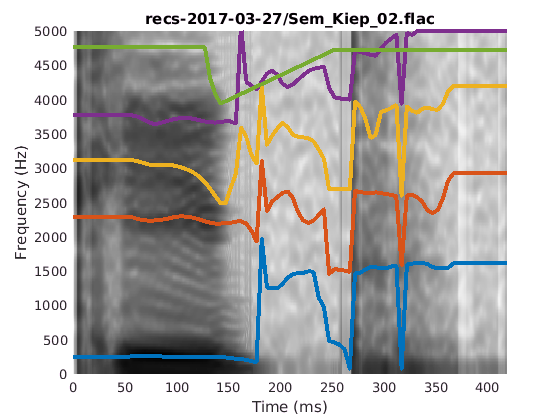

spectime('recs-2017-03-27/Sem_Kiep_02.flac', fparams);

**Octave notes:** This function will probably not work with Octave (issues with graphical display). I should test it through the various graphical toolkits.

The specg_getpoint.m function displays a spectrogram with overlapped formant tracks and measures the time / frequency position of the mouse click (this is simply printed in the terminal). It can be used to estimate the position that is to be used for the measurement of target formant frequencies in the stimulus vowel. Be careful that some phonetic sequences may not be easy to segment on the basis of visual analysis only (it takes some experience to do it). Therefore, I've added the file name as the figure title in order to have some cues to the phonetic sequence. For example, below is the spectrogram of a stop-vowel-nasal sequence. The "boundary" between the vowel and nasal is not easily accessible.

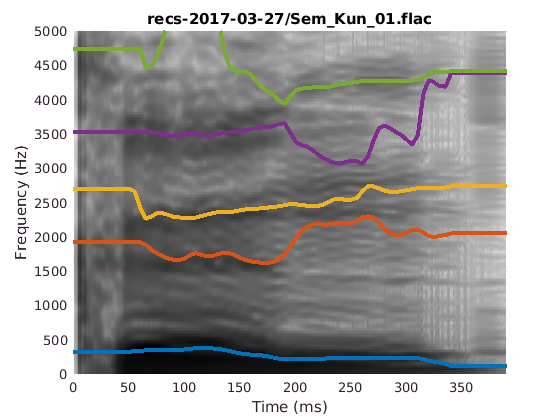

spectime('recs-2017-03-27/Sem_Kun_01.flac', fparams);

It's clear to me that the vowel mid-point stands around 100ms and that there's a relatively important change from vowel to nasal at around 200ms but it may require to "know" that it's a VN sequence in order to take this decision.

## Planification of final processing

The generation of the stimuli is processed in the file `generationStimuli.m`.

The aim of this script is to provide a matlab process that will let us generate speech continua between a series of 2 endpoints for each pair of stimuli (e.g. [kip] ~ [kIp], [kIp] ~ [kEp]... for various utterances). In order to do that, we will have to measure formant frequencies at a temporal point that is adequate as we will create a continuum between e.g. the [I] and [E] formants for each pair.

The scripts works from text file inputs in which each exemplar produced by each speaker will be associated with the time position corresponding to the vowel mid-point (another approach may be an interval start / end of the vowel but as for now, I've choosen to use the mid-point approach). The corresponding structure is displayed in a csv file named pairings.csv and the time positions are stored in midV.csv. Both files are used:

- `pairings.csv` provides the basic structure of contrasts between vowels. It is used to generate a set of permutations based on stimulus repetitions (each speaker utters 4 different versions of the same CVC word);

- `midV.csv` provides the time positions (in ms) that are relevant for vowel formant extraction;

The script `generateStimuli.m` reads these two files. For each pair, 4 random permutations of the repetitions are choosen (e.g. Kiep_01 with Kip_03, Kiep_02 with Kip_01, Kiep_03 with Kip_04 and Kiep_04 with Kip_02). Stable seeds to the random number generator are used in order to regenerate the very same pairs each time the script is run. In order to correct for local variations in formant measurements, `generateStimuli.m` measures the average formant frequency in the interval 25ms before and 25ms after the middle of the vowel. After formant extraction, a continuum of F1 and F2 frequencies is generated in the Bark domain in both directions (e.g. from Kiep_01 to Kip_03 then from Kip_03 to Kiep_01) using a specific number of steps  between the two endpoints. As for now, 7 steps are generated that include the endpoints. The corresponding speech signals are then generated using STRAIGHT_TP. If the logical variable `savestorage` is set to `true` at the beginning of `generationStimuli.m`, the sound sequences are stored in the `sound` directory. The suffix number (between 0 and N) gives an information on the distance from the starting endpoint.

I've added spectral envelope smoothing to the processing.

I still have to check each signal from the set of generated ones.

## Version compatibility (to be checked further)

I've recently experienced issues with Matlab version using get_formants from pyPraat. I've been puzzled by the reasons why this occured. I first thought that it was due to the Python version (3 vs. 2.7). Then I turned back to Matlab R2016b, thinking that this issue would be solved but it actually did not. However I had changed some aspects of get_formants.py in the mean time, trying to solve the issue.

As for now the issue is solved for my case but is still not resolved for use with Matlab R2017a.

(These are partly due to changes between R2016c and R2017a that have introduced incompatibilities with Python calls in get_formants.py. First, Python call uses Python3 (issues with print expression with no parentheses) but there are other more complex issues that occur.

get_formants.py : modified print X with print(X)

`Traceback (most recent call last):`

`  File "/home/crouzet-o/work/lib/UMCG/matlab/pyPraat/get_formants.py", line 261, in <module>`

`    filename_formant, c, o, e = call(args)`

`  File "/home/crouzet-o/work/lib/UMCG/matlab/pyPraat/get_formants.py", line 92, in call`

`    open(praat_script_name, 'wb').write(praat_script)`

`TypeError: a bytes-like object is required, not 'str'`

The praat_script_name file is opened as a binary file but will later be filled with string data.

Line self.f = [x.strip() for x in open(filename, 'rb')]

)